**Question 2 Bessel**

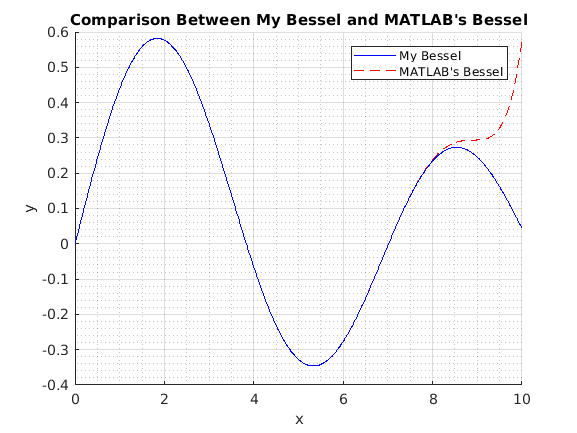

close all;clear all;clc
%construct a vector of equall spaced points between 0 and 10
x=0:0.01:10;
%construct a vector of zeros, the same length as x, that will
%ultimately hold the values of the sum of the first 11 terms in equation
%(1)
Jtrunc=zeros(1,length(x));
%Order of Bessel function (of the first kind)
nu=1;
for n=1:11
    m=n-1; %This is m in equation (1), ranging from 0 to 0
    %Next evaluate the constant term in the sum in (1) for the given m
    constant=((-1)^m)/(factorial(m)*gamma(m+nu+1));
    %Update values in Jtrunc (sum at each x-coordinate)
    Jtrunc=Jtrunc+constant*(x./2).^(2*m+nu);
end
%Determine more accurate representation of the Bessel function using
%MATLAB’s bessej function
Jexact=besselj(1,x);
figure(1);clf;hold on
plot(x,Jexact,'b')
plot(x,Jtrunc,'r--')
xlabel('x')
ylabel('J_{1}(x)')
legend('MATLAB function','Truncated series')

% if you run this you will see they are perfectly
% superimposed, my answer and his, so it's all good.
hold on
besselPlotCompare